# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_slcm.mlx
    ------------
    This code solves firm's investment problem.

%}

## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('C:\Users\khuct\Downloads\Conve__Adjustment_export'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\khuct\Downloads\Conve__Adjustment_export 



## Set the parameters for small and large firm

% Setup and solve model for small firms
fprintf('\nSolving model for small firms...\n');


Solving model for small firms...


par_small = model.setup('small');
par_small = model.gen_grids(par_small);
sol_small = solve.firm_problem(par_small);

------------Beginning Value Function Iteration.------------

Iteration: 10, Diff: 0.638563
Iteration: 20, Diff: 0.123268
Iteration: 30, Diff: 0.061238
Iteration: 40, Diff: 0.035975
Iteration: 50, Diff: 0.021501
Iteration: 60, Diff: 0.012871
Iteration: 70, Diff: 0.007706
Iteration: 80, Diff: 0.004614
Iteration: 90, Diff: 0.002763
Iteration: 100, Diff: 0.001654
Iteration: 110, Diff: 0.000990
Iteration: 120, Diff: 0.000593
Iteration: 130, Diff: 0.000355
Iteration: 140, Diff: 0.000213
Iteration: 150, Diff: 0.000127
Iteration: 160, Diff: 0.000076
Iteration: 170, Diff: 0.000046
Iteration: 180, Diff: 0.000027
Iteration: 190, Diff: 0.000016
Iteration: 200, Diff: 0.000010
Iteration: 210, Diff: 0.000006
Iteration: 220, Diff: 0.000004
Iteration: 230, Diff: 0.000002
Iteration: 240, Diff: 0.000001

Converged in 245 iterations.

------------End of Value Function Iteration.------------



% Setup and solve model for large firms
fprintf('\nSolving model for large firms...\n');


Solving model for large firms...


par_large = model.setup('large');
par_large = model.gen_grids(par_large);
sol_large = solve.firm_problem(par_large);

------------Beginning Value Function Iteration.------------

Iteration: 10, Diff: 1.832410
Iteration: 20, Diff: 0.157147
Iteration: 30, Diff: 0.037655
Iteration: 40, Diff: 0.019831
Iteration: 50, Diff: 0.011703
Iteration: 60, Diff: 0.006993
Iteration: 70, Diff: 0.004186
Iteration: 80, Diff: 0.002506
Iteration: 90, Diff: 0.001500
Iteration: 100, Diff: 0.000898
Iteration: 110, Diff: 0.000538
Iteration: 120, Diff: 0.000322
Iteration: 130, Diff: 0.000193
Iteration: 140, Diff: 0.000115
Iteration: 150, Diff: 0.000069
Iteration: 160, Diff: 0.000041
Iteration: 170, Diff: 0.000025
Iteration: 180, Diff: 0.000015
Iteration: 190, Diff: 0.000009
Iteration: 200, Diff: 0.000005
Iteration: 210, Diff: 0.000003
Iteration: 220, Diff: 0.000002
Iteration: 230, Diff: 0.000001

Converged in 233 iterations.

------------End of Value Function Iteration.------------


% Plot policy functions for each type of firm
fprintf('\nPlotting policy functions...\n');


Plotting policy functions...


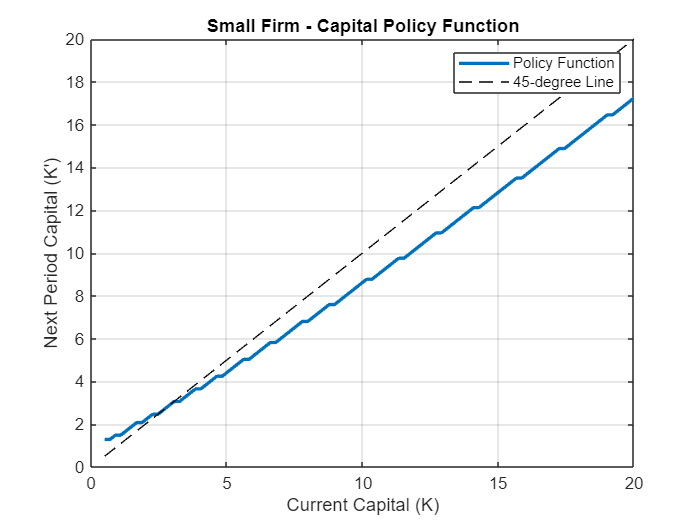

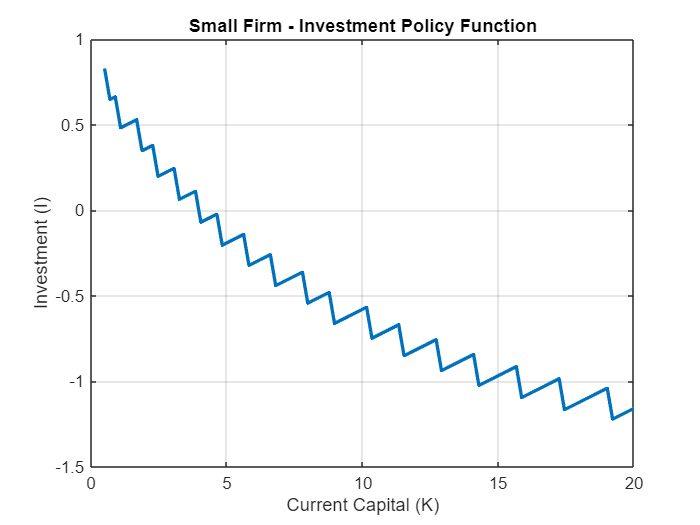

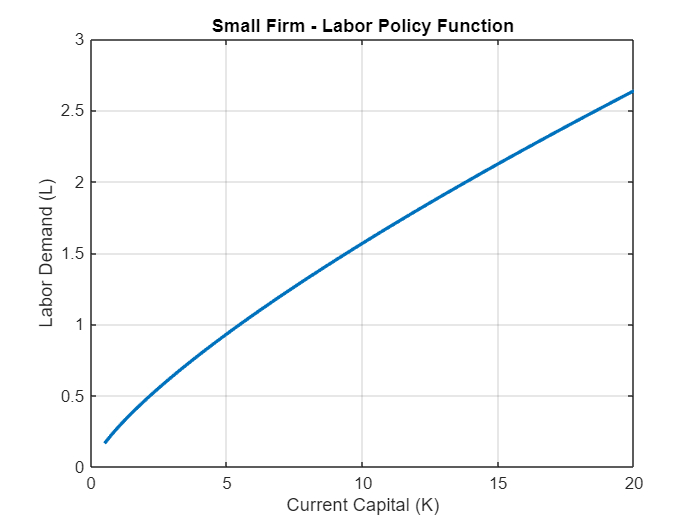

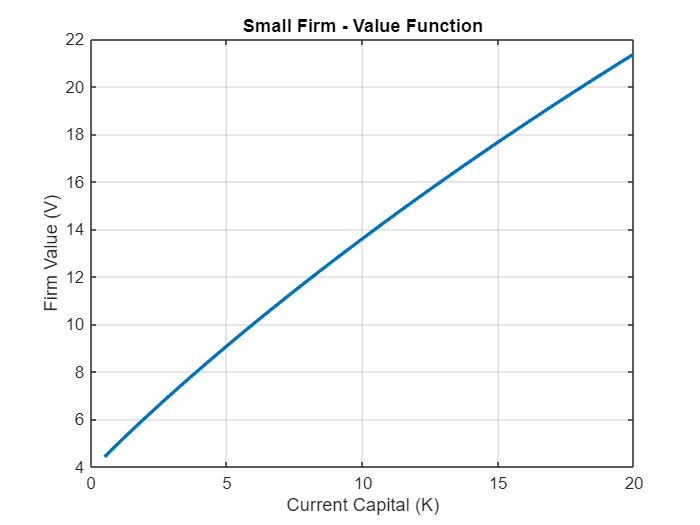

my_graph.plot_policy(par_small, sol_small, 'Small');

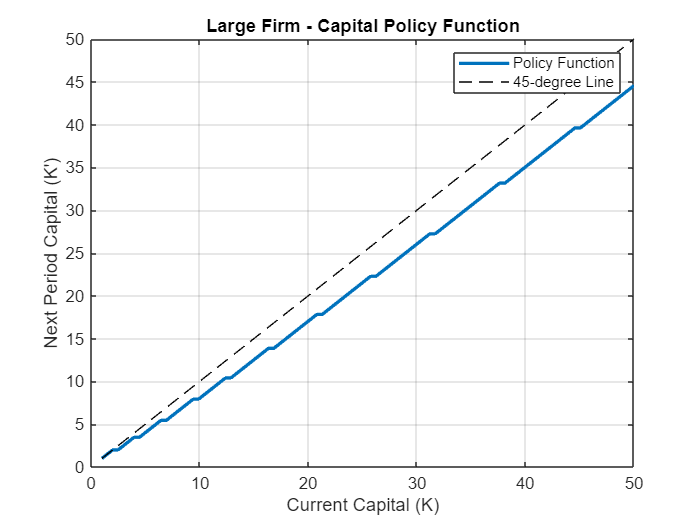

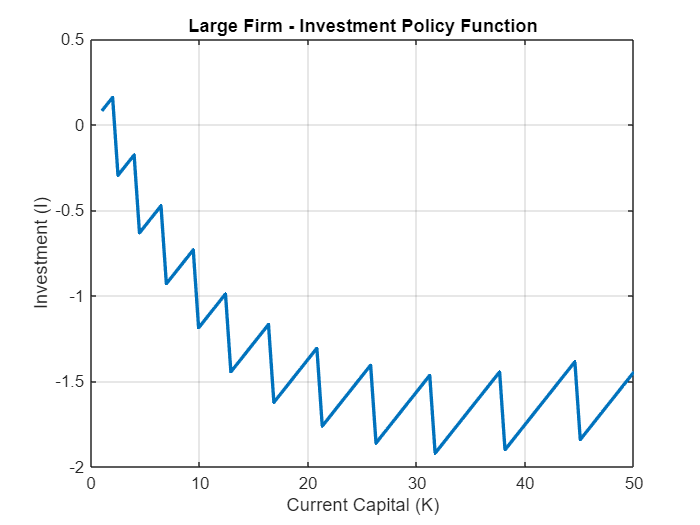

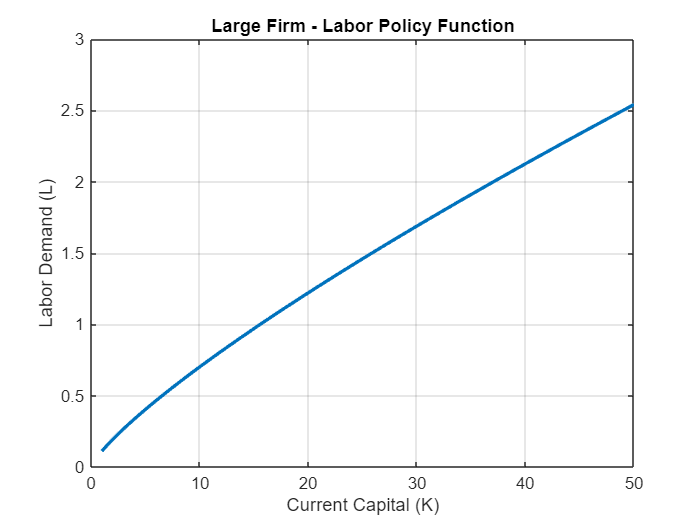

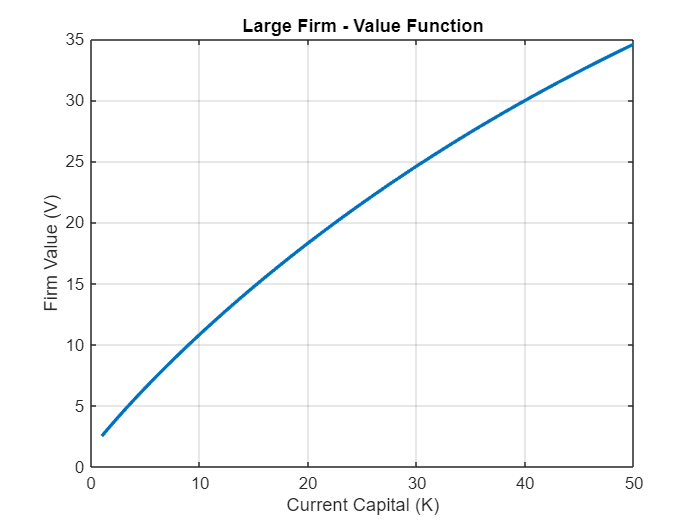

my_graph.plot_policy(par_large, sol_large, 'Large');

## Simulate and plot the models

% Simulate models
fprintf('\nSimulating firm dynamics...\n');


Simulating firm dynamics...


sim_small = simulate.firm_dynamics(par_small, sol_small);
sim_large = simulate.firm_dynamics(par_large, sol_large);

% Plot simulation results
fprintf('\nPlotting simulation results...\n');


Plotting simulation results...


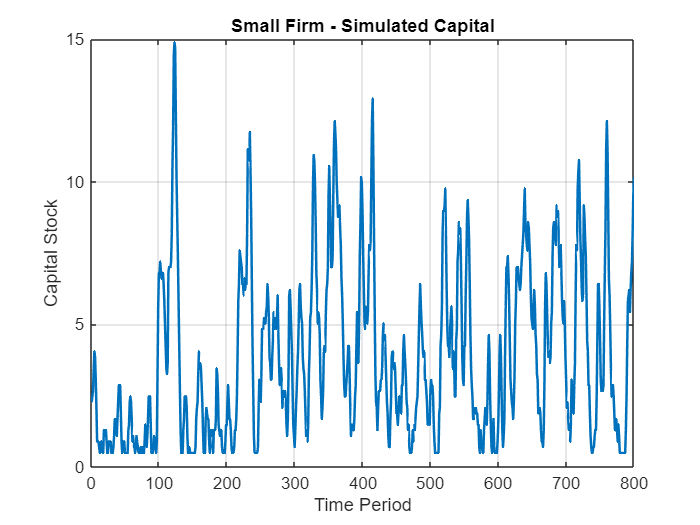

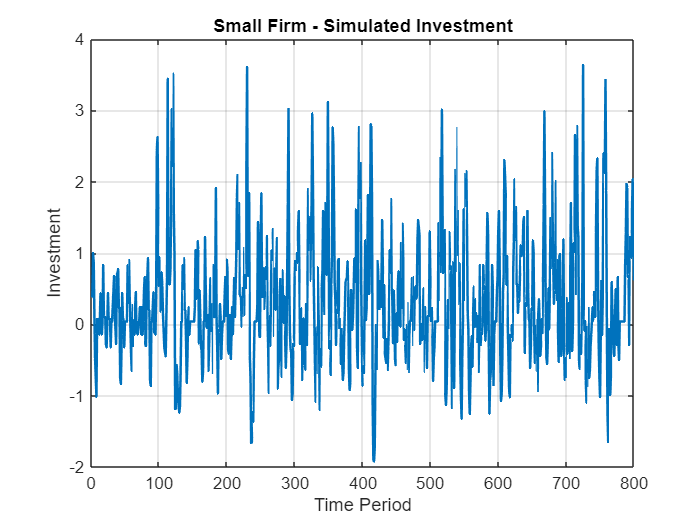

my_graph.plot_simulation(sim_small, 'Small');

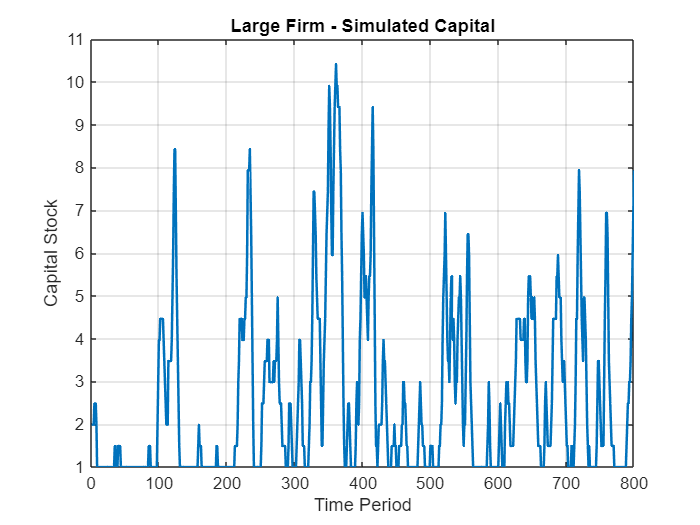

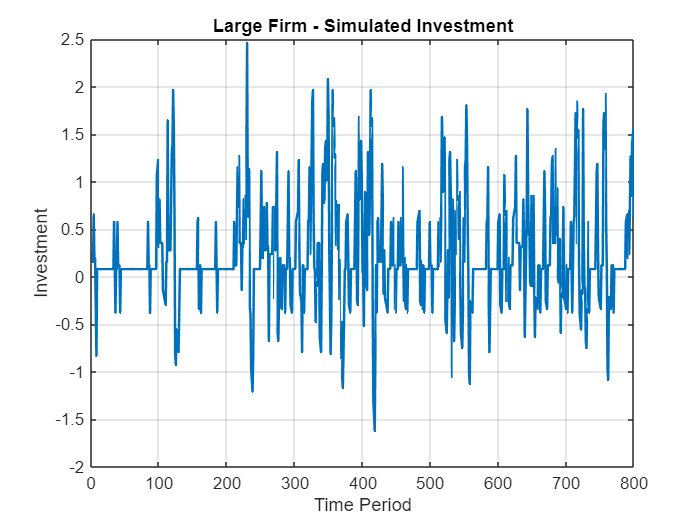

my_graph.plot_simulation(sim_large, 'Large');

## Parameter analysis

% Parameter analysis
fprintf('\nPerforming parameter analysis...\n');


Performing parameter analysis...


------------Beginning Value Function Iteration.------------

Iteration: 10, Diff: 2.490332
Iteration: 20, Diff: 0.426919
Iteration: 30, Diff: 0.110150
Iteration: 40, Diff: 0.045413
Iteration: 50, Diff: 0.024294
Iteration: 60, Diff: 0.014135
Iteration: 70, Diff: 0.008405
Iteration: 80, Diff: 0.005024
Iteration: 90, Diff: 0.003007
Iteration: 100, Diff: 0.001800
Iteration: 110, Diff: 0.001078
Iteration: 120, Diff: 0.000645
Iteration: 130, Diff: 0.000386
Iteration: 140, Diff: 0.000231
Iteration: 150, Diff: 0.000139
Iteration: 160, Diff: 0.000083
Iteration: 170, Diff: 0.000050
Iteration: 180, Diff: 0.000030
Iteration: 190, Diff: 0.000018
Iteration: 200, Diff: 0.000011
Iteration: 210, Diff: 0.000006
Iteration: 220, Diff: 0.000004
Iteration: 230, Diff: 0.000002
Iteration: 240, Diff: 0.000001

Converged in 247 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 10, Diff: 2.257823
Iteration: 20, Diff: 0.31

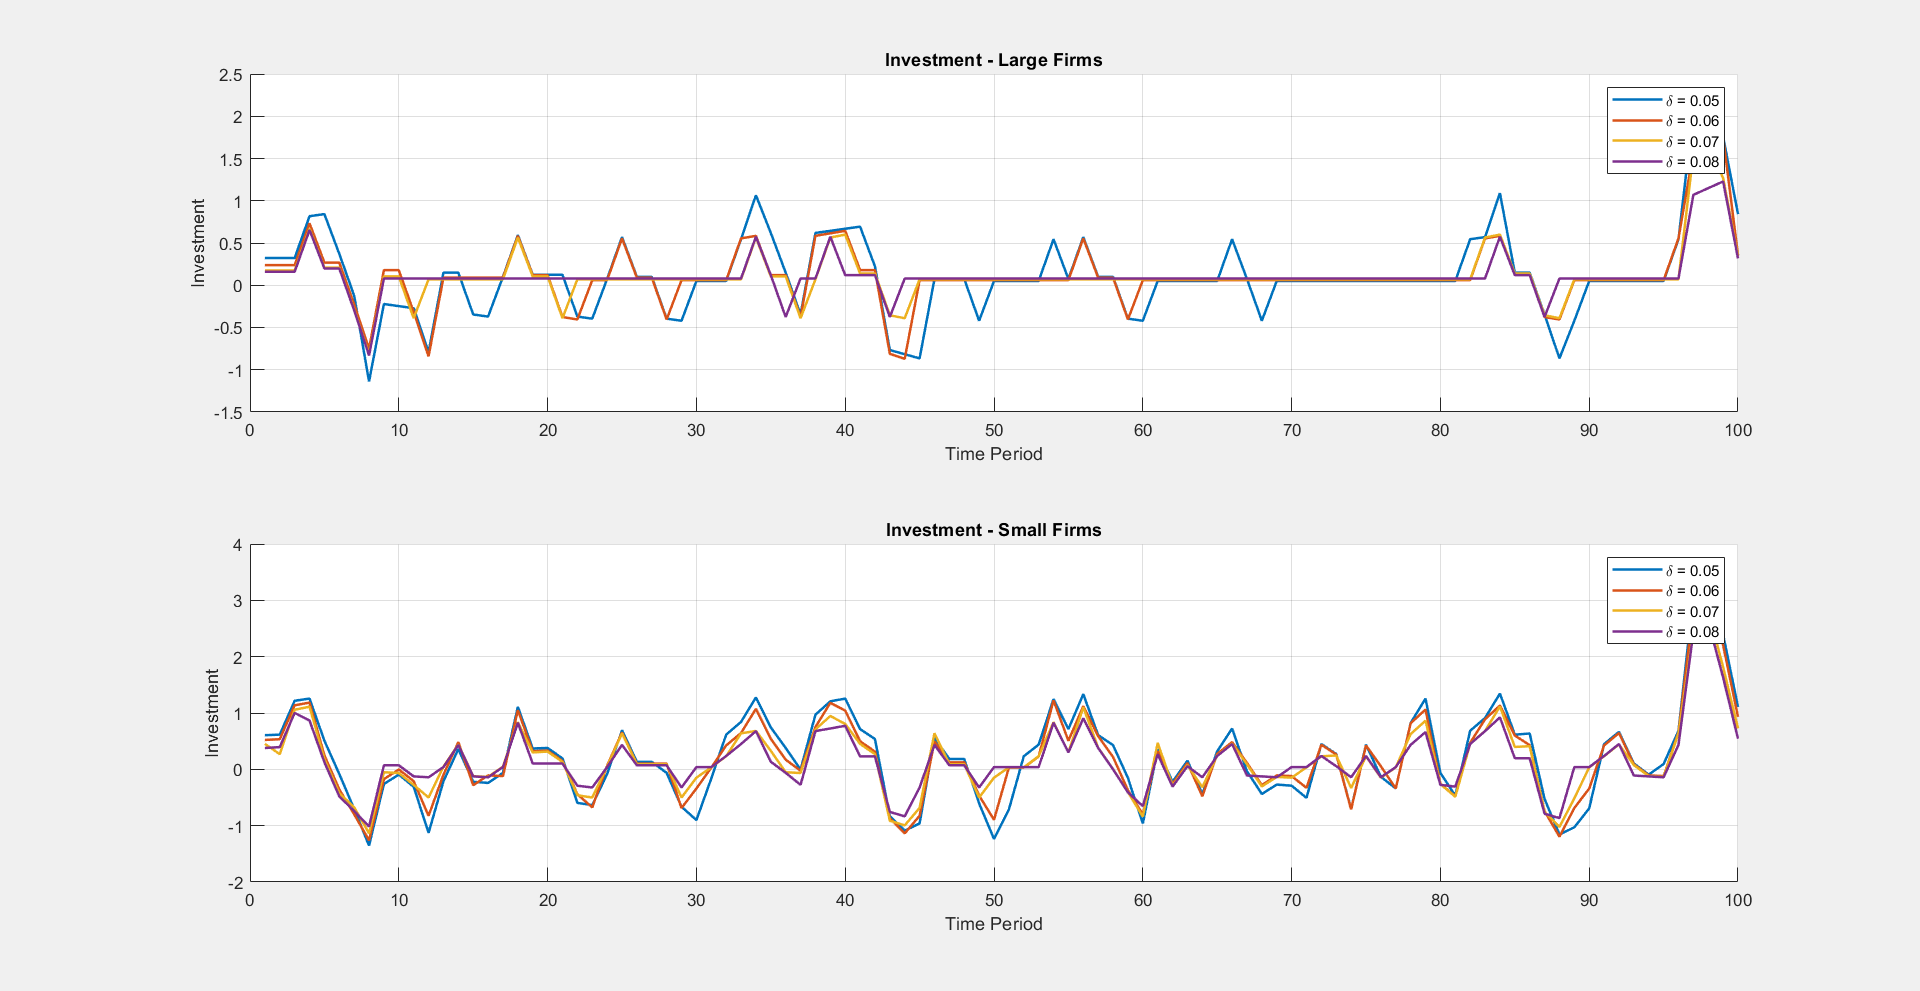

my_graph.plot_delta_analysis(par_large, sol_large, par_small, sol_small);

------------Beginning Value Function Iteration.------------

Iteration: 10, Diff: 1.832410
Iteration: 20, Diff: 0.157147
Iteration: 30, Diff: 0.037655
Iteration: 40, Diff: 0.019831
Iteration: 50, Diff: 0.011703
Iteration: 60, Diff: 0.006993
Iteration: 70, Diff: 0.004186
Iteration: 80, Diff: 0.002506
Iteration: 90, Diff: 0.001500
Iteration: 100, Diff: 0.000898
Iteration: 110, Diff: 0.000538
Iteration: 120, Diff: 0.000322
Iteration: 130, Diff: 0.000193
Iteration: 140, Diff: 0.000115
Iteration: 150, Diff: 0.000069
Iteration: 160, Diff: 0.000041
Iteration: 170, Diff: 0.000025
Iteration: 180, Diff: 0.000015
Iteration: 190, Diff: 0.000009
Iteration: 200, Diff: 0.000005
Iteration: 210, Diff: 0.000003
Iteration: 220, Diff: 0.000002
Iteration: 230, Diff: 0.000001

Converged in 233 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 10, Diff: 2.284815
Iteration: 20, Diff: 0.246908
Iteration: 30, Diff: 0.043

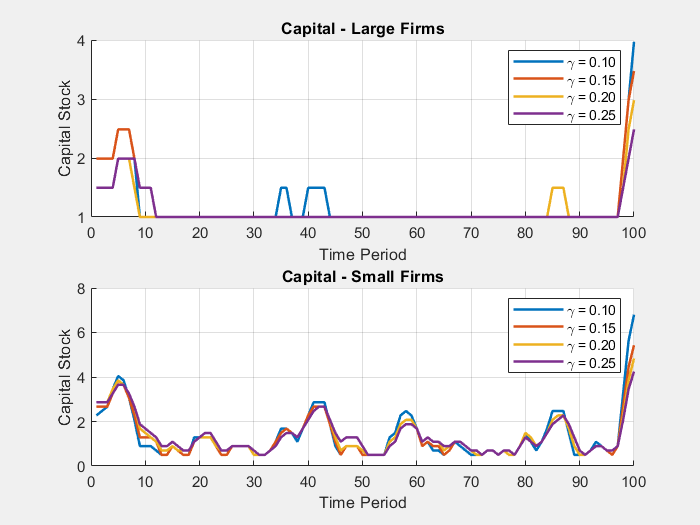

------------Beginning Value Function Iteration.------------

Iteration: 10, Diff: 1.832410
Iteration: 20, Diff: 0.157147
Iteration: 30, Diff: 0.037655
Iteration: 40, Diff: 0.019831
Iteration: 50, Diff: 0.011703
Iteration: 60, Diff: 0.006993
Iteration: 70, Diff: 0.004186
Iteration: 80, Diff: 0.002506
Iteration: 90, Diff: 0.001500
Iteration: 100, Diff: 0.000898
Iteration: 110, Diff: 0.000538
Iteration: 120, Diff: 0.000322
Iteration: 130, Diff: 0.000193
Iteration: 140, Diff: 0.000115
Iteration: 150, Diff: 0.000069
Iteration: 160, Diff: 0.000041
Iteration: 170, Diff: 0.000025
Iteration: 180, Diff: 0.000015
Iteration: 190, Diff: 0.000009
Iteration: 200, Diff: 0.000005
Iteration: 210, Diff: 0.000003
Iteration: 220, Diff: 0.000002
Iteration: 230, Diff: 0.000001

Converged in 233 iterations.

------------End of Value Function Iteration.------------
------------Beginning Value Function Iteration.------------

Iteration: 10, Diff: 2.284815
Iteration: 20, Diff: 0.246908
Iteration: 30, Diff: 0.043

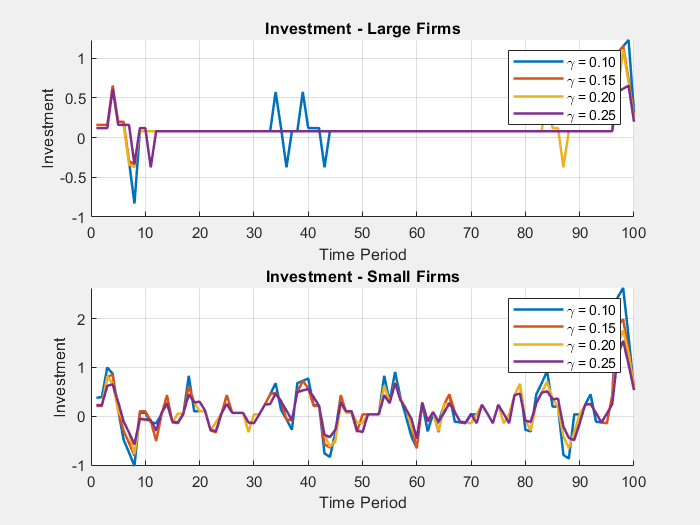

my_graph.plot_gamma_analysis(par_large, sol_large, par_small, sol_small);


% Heat map analysis
fprintf('\nGenerating heat maps...\n');


Generating heat maps...


results_small = simulate.parameter_analysis('small');


Performing parameter analysis for small firms...
  Testing gamma = 0.10, delta = 0.05
------------Beginning Value Function Iteration.------------

Iteration: 10, Diff: 0.903486
Iteration: 20, Diff: 0.238681
Iteration: 30, Diff: 0.116152
Iteration: 40, Diff: 0.066274
Iteration: 50, Diff: 0.039257
Iteration: 60, Diff: 0.023449
Iteration: 70, Diff: 0.014033
Iteration: 80, Diff: 0.008401
Iteration: 90, Diff: 0.005030
Iteration: 100, Diff: 0.003012
Iteration: 110, Diff: 0.001803
Iteration: 120, Diff: 0.001080
Iteration: 130, Diff: 0.000646
Iteration: 140, Diff: 0.000387
Iteration: 150, Diff: 0.000232
Iteration: 160, Diff: 0.000139
Iteration: 170, Diff: 0.000083
Iteration: 180, Diff: 0.000050
Iteration: 190, Diff: 0.000030
Iteration: 200, Diff: 0.000018
Iteration: 210, Diff: 0.000011
Iteration: 220, Diff: 0.000006
Iteration: 230, Diff: 0.000004
Iteration: 240, Diff: 0.000002
Iteration: 250, Diff: 0.000001

Converged in 257 iterations.

------------End of Value Function Iteration.-----------

results_large = simulate.parameter_analysis('large');


Performing parameter analysis for large firms...
  Testing gamma = 0.10, delta = 0.05
------------Beginning Value Function Iteration.------------

Iteration: 10, Diff: 2.490332
Iteration: 20, Diff: 0.426919
Iteration: 30, Diff: 0.110150
Iteration: 40, Diff: 0.045413
Iteration: 50, Diff: 0.024294
Iteration: 60, Diff: 0.014135
Iteration: 70, Diff: 0.008405
Iteration: 80, Diff: 0.005024
Iteration: 90, Diff: 0.003007
Iteration: 100, Diff: 0.001800
Iteration: 110, Diff: 0.001078
Iteration: 120, Diff: 0.000645
Iteration: 130, Diff: 0.000386
Iteration: 140, Diff: 0.000231
Iteration: 150, Diff: 0.000139
Iteration: 160, Diff: 0.000083
Iteration: 170, Diff: 0.000050
Iteration: 180, Diff: 0.000030
Iteration: 190, Diff: 0.000018
Iteration: 200, Diff: 0.000011
Iteration: 210, Diff: 0.000006
Iteration: 220, Diff: 0.000004
Iteration: 230, Diff: 0.000002
Iteration: 240, Diff: 0.000001

Converged in 247 iterations.

------------End of Value Function Iteration.------------
  Testing gamma = 0.10, delta

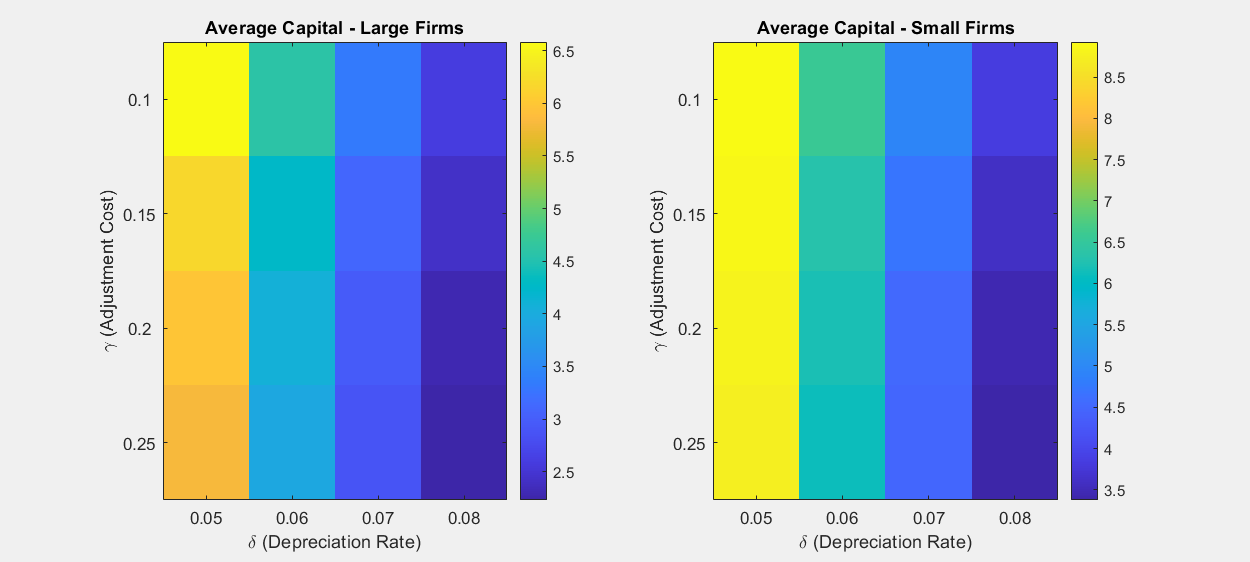

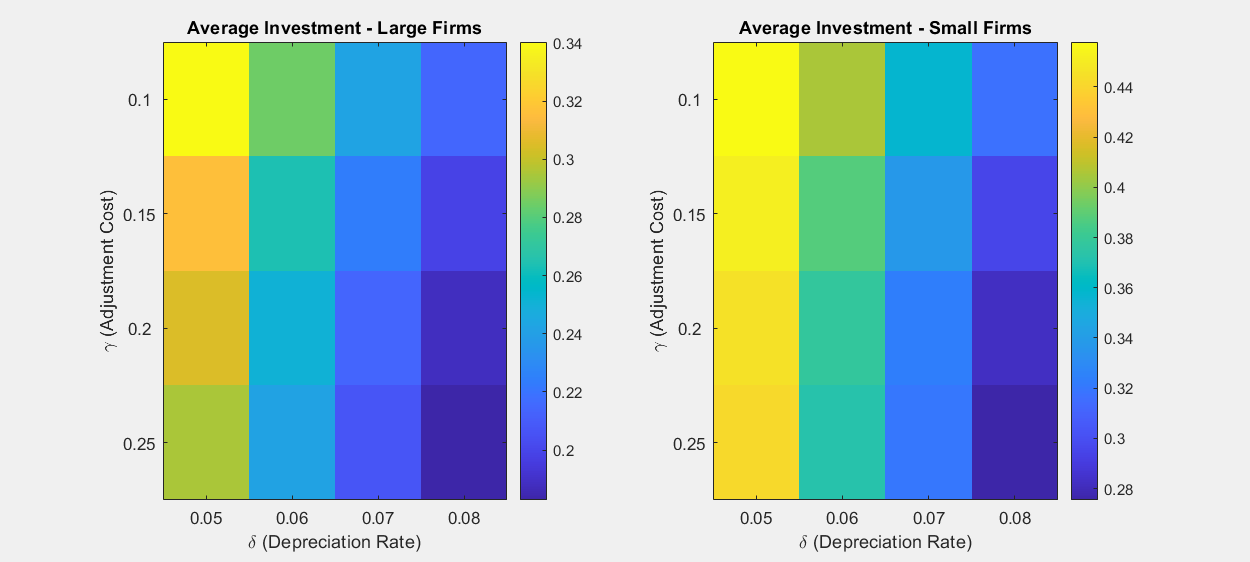

my_graph.plot_parameter_heatmaps(results_large, results_small);


fprintf('\nAnalysis complete.\n');


Analysis complete.
